# Analysis of Gene Expression Data for Different Cancer Types

## Background

The dataset that we will be working with comes from** The Cancer Genome Atlas (TCGA) project**, which began in 2006 and established a foundation for cancer genomics research. This project involved high-throughput sequencing techniques that were used to collect a variety of **-omics data**. Specifically, these are: 

- Genomic: DNA sequences

- Transcriptomic: gene expression (mRNA)

- Epigenomic: genetic modifications (e.g. methylation)

- Proteomic: protein expression and structure

Over the years, these datasets have been analyzed in a variety of ways by both the TCGA program and other researchers. The image below shows the most recent status from the TCGA webpage: 

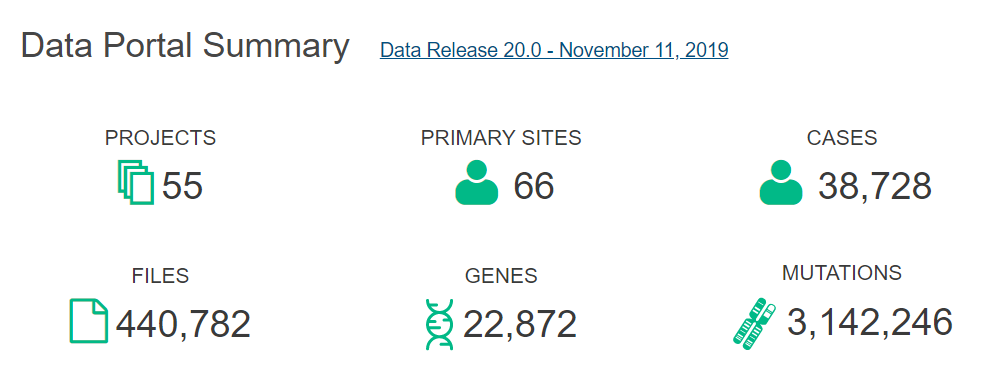

For today's lecture, we will be analyzing **transcriptomic** data collected from 100 cancer patients. This dataset includes mRNA expression values for 1000 genes, which are organized as columns. Therefore, we will be dealing with a 100 x 1000 matrix of gene expression data.

Our main goal is to identify how many cancer types are represented and determine what these are specifically based on which genes are highly expressed or suppressed. 

## Exploratory Analysis of TCGA RNAseq Data

### Load and examine the data

To start, you'll need to load the dataset (*cancer_RNAseq_data.xlsx*). We'll also want to create a variable to store the patient IDs, a variable to store the gene names, and one more variable to store the gene expression data as a double array. 

% Load the dataset

% Create a variable for patient IDs

% Create a variable for gene names

% Create a variable for gene expression data


Create a histogram for the gene expression values: 

% Histogram of data


Questions: What do you notice about the values? 

### Visualize the data using hierarchical clustering

Create a clustergram of the gene expression data, using the patient IDs to label the rows and the gene names to label the columns. Also be sure to standardize all values by column:

% Create clustergram (label rows, label columns, and standardize by
% columns)





Question: Based on what you see, do you think that this data is able to distinguish different cancer types? If so, how many do you think are represented?

#### Additional exploration

The clustergram window has various interactive functionalities that allow the user to further explore the data. For example, we can insert a color bar by cliking the colorbar icon at the top (as shown below):

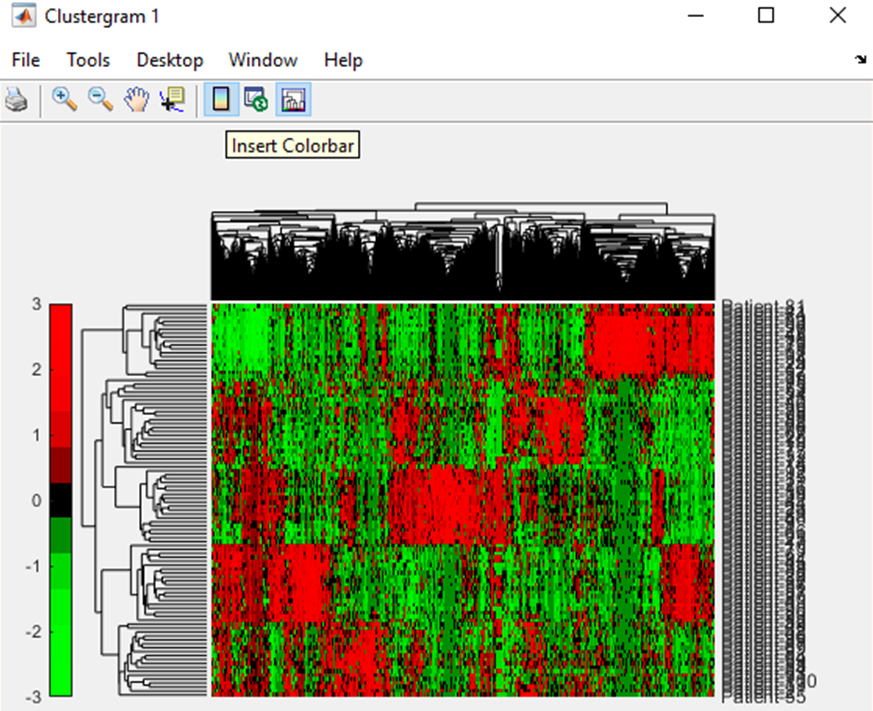

We can also look at a particular cluster in greater detail by right-clicking on a branch point and selecting *Copy Group to New Clustergram*:

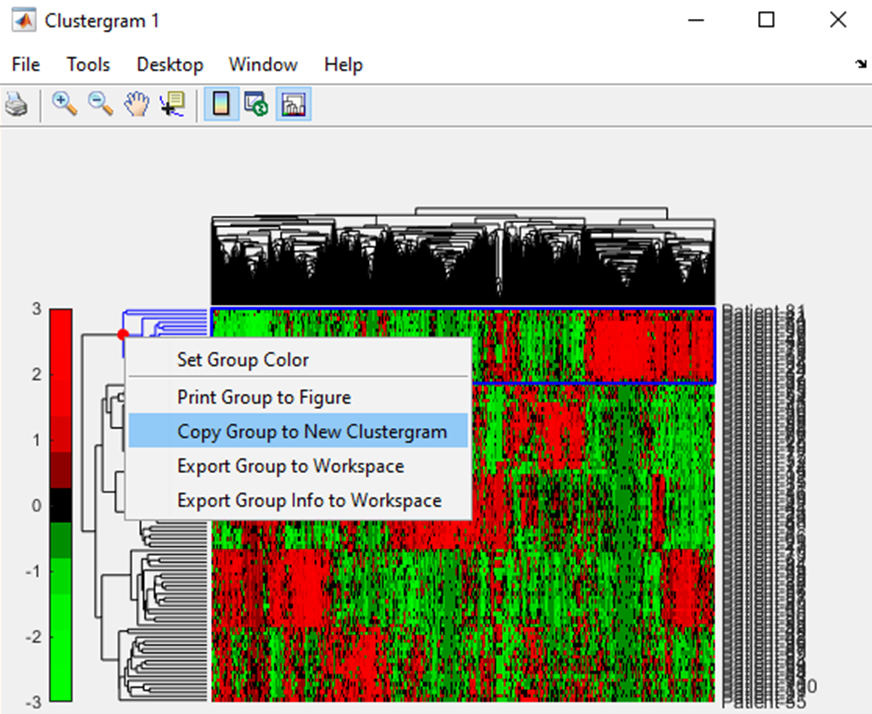

If you left-click and hold on a branch point, you will also be able to see the labels associated for that cluster:

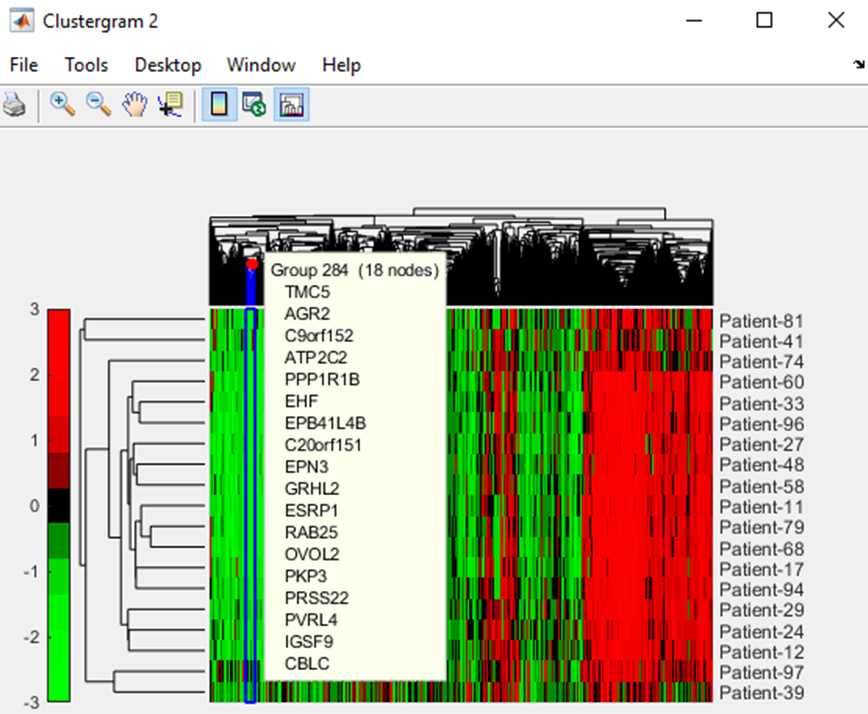

Select any row cluster of your choice and generate a new clustergram. Explore which genes cluster together, and determine whether these are up- or down-regulated.

Question: Are there any genes that you recognize? If so, what does this gene do?

Extra: The default color palette used is red-green, but this may not be optimal for certain reasons (e.g. colorblind audience). We can modify the color palette by specifying the *Colormap* option. One built-in alternative option is *redbluecmap*, which is often more intuitive than the red-green default when interpreting gene expression data. The image below shows what the TCGA clustergram looks like using a red-blue colormap (refer to answer key for code):

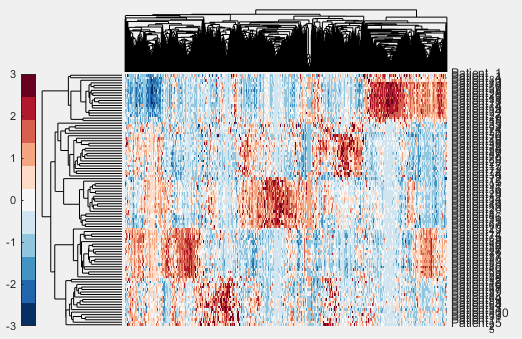

### Determine the best cluster number (k) estimate using k-means clustering

We'll now use k-means clustering to quantitatively determine the best estimate for how many clusters (types of cancers) are represented in our dataset. 

For this task, create a for-loop to calculate the silhouette statistic for k values ranging from 2 to 10. Below is a basic template to help you get started (you'll only need to modify the parts in curly brackets): 

% Create a vector of k values ranging from 2 to 10
{vector of k values}

% For-loop to calculate the silhouette statistic for different k values
n = length({vector of k values});   % number of k values
s_statistic = zeros(n,1);           % variable to store silhouette statistic values
for i = 1:n
    % Use the kmeans function to cluster patients into k clusters
    [idx,~] = kmeans({gene expression data},{k value});
    % Use the silhouette function to calculate silhouette values
    s = silhouette({gene expression data},idx);
    % Calculate a weight value proportional to positive silhouette values
    weight = sum(s > 0)/length(s);
    % Calculate the silhouette statistic by multiplying the weight with the
    % mean of silhouette values and store this to s_statistic
    s_statistic(i) = weight*mean(s);
end

Question: What is the value for the max silhouette statistic? Which k value does this correspond with? 

Based on your answer to the question above, generate a silhouette plot:

% Silhouette plot based on best k value



Question: Are there any negative silhouette values? If so, how many are there in total?

### Re-visualize the data in lower-dimension using PCA

Now we'll apply principal component analysis (PCA) to re-visualize our data within a lower-dimensional space:

% Apply PCA to the gene expression data (use patient IDs for labeling)


Question: Based on the plot of PC1 vs. PC2, how many distinct clusters can you identify? How much variance do PC1 and PC2 account for?

Activity: Highlight one of the distinct clusters in the plot of PC1 vs. PC2. Do the patients for this cluster match with any row cluster from our clustergram?

## Additional Questions and Practice

For the following questions, you will need to load another file (*cancer_RNAseq_subset.xlsx*), which is a reduced subset of our gene expression data. Follow the same steps for creating variables for patient IDs, gene names, and gene expression data:

% Load the data subset

% Create a variable for patient IDs

% Create a variable for gene names

% Create a variable for gene expression data


Question: How many genes are included for this data subset?

Generate a clustergram of this data, labeling the rows and columns and standardizing by column:

% Clustergram of data subset





The **AR gene** codes for the **androgen receptor**, and its up-regulation is associated with certain types of cancer. 

Question: Which cancer types are associated with up-regulation of the AR gene? 

Question: Considering that one or more of these cancer types are represented in our dataset, which patient cluster or clusters do you think these correspond to?

Extra: Look up all the remaining genes. Can you guess what other cancer types might be represented in our dataset?

## Confirm Predictions using Cancer Classification Data

The classifcation data for all 100 patients is available in another file (*cancer_RNAseq_class.txt*). We'll use this information to confirm whether our predictions from data exploration were right or not. 

% Load the classification data


Re-generate our clustergram from earlier, only this time, use the patient classification for labeling the rows: 

% Re-generate clustergram (label rows based on classification)





The classification data is provided as acronyms used by TCGA. This [link](https://github.com/greenelab/pancancer/blob/master/data/tcga_dictionary.tsv) provides information on which cancer type each acronym corresponds with. 

Question: How many cancer types are represented in our dataset? Which cancer types are these?

Re-generate our PCA plot from earlier, using patient classification as labels:

% Re-generate PCA plot (labels based on classification)
